clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## ILMI

listOfUncertainties = {[-1,1]};
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end
B = @(i) param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd);
tol = 1e-2;
tol_alpha = 0.005;

s=tf('s');
param.model.Dwz = 80*eye(4);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0.01*eye(4);



% Step 1
yalmip('clear')

q = cell(param.n);
y = cell(param.n);
%fill in p^-1
for i = 1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
Q_hat = sdpvar(28,28);
Y_hat = [sdpvar(4,28,'full')];
%insert Q into Q_hat
Q_hat(1:12,1:12) = blkdiag(q{:});
%insert Y into y_hat
Y_hat(1:4,1:12) = blkdiag(y{:});
gamma = sdpvar(1);

%constraints
constriants = [];

%Define the lyapunaov constraint for the decoupled system 
Lyap = param.model.A * Q_hat(1:param.n*3,1:param.n*3) + Q_hat(1:param.n*3,1:param.n*3) * param.model.A.' + param.model.B_Bar * Y_hat(1:param.n,1:param.n*3) + Y_hat(1:param.n,1:param.n*3).' * param.model.B_Bar.';
    constriants = [constriants, Lyap <= 0, Q_hat(1:param.n*3,1:param.n*3) >= 0];

%Define the parameters for desired response
A = param.model.A + (0)*eye(12);

A_bar = [param.model.A, param.model.Bw*param.model.Cww, zeros(12,4),zeros(12,4),zeros(12,4);
         zeros(4,12),param.model.Aww, zeros(4),zeros(4),zeros(4);
         param.model.Bwz*param.model.Cz, -param.model.Bwz*param.model.DWref*param.model.Cww, param.model.Awz, -param.model.Bwz*param.model.CWref,zeros(4);
         zeros(4,12),param.model.BWref*param.model.Cww, zeros(4),param.model.AWref,zeros(4);
         zeros(4,12), zeros(4),zeros(4),zeros(4),param.model.AWu]; 

B_bar = @(k) [B(k);
             zeros(4,4);
             zeros(4,4);
             zeros(4,4);
             param.model.BWu];

B_DS = [param.model.Bw*param.model.Dww;
         param.model.Bww;
         -param.model.Bwz*param.model.DWref*param.model.Dww;
         param.model.BWref*param.model.Dww;
         zeros(4,4)];

C1_bar = [param.model.Dwz*param.model.Cz, -param.model.Dwz*param.model.DWref*param.model.Cww, param.model.Cwz,-param.model.Dwz*param.model.CWref,zeros(4);
      zeros(4,12),zeros(4),zeros(4),zeros(4),param.model.CWu];

C2_bar = [zeros(4,4);
      param.model.DWu];

D_Bar = [-param.model.Dwz*param.model.DWref*param.model.Dww;
        zeros(4,4);];

constraints = [param.model.A * Q_hat(1:12,1:12) + Q_hat(1:12,1:12) * param.model.A.' + param.model.B_Bar * Y_hat(1:4,1:12) + Y_hat(1:4,1:12).' * param.model.B_Bar.' <=0];
for i=1:length(Uncertainties)
    constraints = [constraints, [Q_hat*A_bar.'+A_bar*Q_hat+Y_hat.'*B_bar(i).'+B_bar(i)*Y_hat, B_DS, Q_hat*C1_bar.'+Y_hat.'*C2_bar.';
                     B_DS.', -gamma*eye(4),D_Bar.';
                     C1_bar*Q_hat+C2_bar*Y_hat, D_Bar, -gamma*eye(8)]<=0];
end
constraints = [constraints,gamma >= 0, Q_hat >=0];

options = sdpsettings('verbose',0,'solver','mosek');
optimize(constraints,[gamma],options)

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0665
       solvertime: 0.2625
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0



y_out = value(Y_hat);
q_out = value(Q_hat);
Ksf = y_out(1:4,1:12)/q_out(1:12,1:12);

temp = (value(Q_hat));
X(:,:,1) = (temp(1:12,1:12)+temp(1:12,1:12).')/2

X = 1.0e+04 *

    0.0004    0.0003   -0.0387         0         0         0         0         0         0         0         0         0
    0.0003    0.0002   -0.0291         0         0         0         0         0         0         0         0         0
   -0.0387   -0.0291    3.7196         0         0         0         0         0         0         0         0         0
         0         0         0    0.0004    0.0003   -0.0380         0         0         0         0         0         0
         0         0         0    0.0003    0.0002   -0.0285         0         0         0         0         0         0
         0         0         0   -0.0380   -0.0285    3.6537         0         0         0         0         0         0
         0         0         0         0         0         0    0.0004    0.0003   -0.0375         0         0         0
         0         0         0         0         0         0    0.0003    0.0002   -0.0282         0         0         0
         0       

i = 1;

while 1
    % Step 2
    yalmip('clear')
    [P, Ksof] = constructVariables(param);
    alpha = sdpvar(1);
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [param.model.A.'*P + P*param.model.A - X(:,:,i)*(B(k)*B(k).')*P - P*(B(k)*B(k).')*X(:,:,i) + X(:,:,i)*(B(k)*B(k).')*X(:,:,i) - alpha*P, (B(k).'*P + Ksof*param.model.CySOF).';
                        (B(k).'*P + Ksof*param.model.CySOF), -eye(param.n)] <= 0]
    end
    constraints = [constraints, P >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = bisection(constraints, alpha, options)
    alpha_min = value(alpha)
    % Step 3
    if(alpha_min <= tol_alpha)
        break
    end
    % Step 4
    yalmip('clear')
    [P, Ksof] = constructVariables(param);
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [param.model.A.'*P + P*param.model.A - X(:,:,i)*(B(k)*B(k).')*P - P*(B(k)*B(k).')*X(:,:,i) + X(:,:,i)*(B(k)*B(k).')*X(:,:,i) - alpha_min*P , (B(k).'*P + Ksof*param.model.CySOF).';
                        (B(k).'*P + Ksof*param.model.CySOF), -eye(param.n)] <= 0];
    end
    constraints = [constraints, P >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = optimize(constraints, trace(P), options);
    P_min(:,:,i) = value(P);
    % Step 5
    if (norm(X(:,:,i) - P_min(:,:,i)) < tol)
        % Step 6
        break
    else
        i = i + 1;
        X(:,:,i) = P_min(:,:,i-1);
    end
end

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   2.5617e-18 to 3771.4146|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   2.5617e-18 to 3771.4146|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 47286.4957|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1369
    solvertime: 0.2930
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 11.9704

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 5028.5391|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 5028.5391|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 63048.4904|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1136
    solvertime: 0.2065
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 4.3056

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   1.0936e-19 to 3996.8415|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   1.0936e-19 to 3996.8415|
|   #2|   Matrix inequality (bilinear) 16x16|   0.0045899 to 50112.9287|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1005
    solvertime: 0.2307
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 2.4261

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   1.7765e-18 to 4019.9501|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   1.7765e-18 to 4019.9501|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 50402.6677|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.0993
    solvertime: 0.1874
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 1.7553

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   2.3757e-18 to 4044.6804|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   2.3757e-18 to 4044.6804|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 50712.7393|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1019
    solvertime: 0.2118
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 1.3635

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   4.6815e-18 to 4032.2933|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   4.6815e-18 to 4032.2933|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 50557.4281|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1025
    solvertime: 0.2059
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 1.0998

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3995.1925|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3995.1925|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 50092.2534|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1150
    solvertime: 0.2167
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.9058

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3944.7448|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3944.7448|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 49459.7334|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1015
    solvertime: 0.2027
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.7549

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3886.9504|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3886.9504|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 48735.0998|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1010
    solvertime: 0.1899
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.6329

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3825.1918|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3825.1918|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 47960.7615|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1013
    solvertime: 0.2006
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.5315

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3761.6861|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3761.6861|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 47164.5188|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1084
    solvertime: 0.2052
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.4453

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3698.1402|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3698.1402|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 46367.7726|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1062
    solvertime: 0.1873
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.3708

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3634.9464|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3634.9464|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 45575.4396|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1128
    solvertime: 0.1851
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.3055

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3572.7984|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3572.7984|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 44796.2194|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1066
    solvertime: 0.2305
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.2476

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3512.0001|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3512.0001|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 44033.9231|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1061
    solvertime: 0.2170
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.1957

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3452.3986|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3452.3986|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 43286.6311|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.1028
    solvertime: 0.1821
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.1489

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3394.5054|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3394.5054|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 42560.7588|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.0873
    solvertime: 0.1495
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.1064

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3338.1047|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|         Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3338.1047|
|   #2|   Matrix inequality (bilinear) 16x16|    0.015297 to 41853.5988|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.0868
    solvertime: 0.1308
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.0675

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|        Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3283.545|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|        Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3283.545|
|   #2|   Matrix inequality (bilinear) 16x16|   0.015297 to 41169.5231|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.0983
    solvertime: 0.1377
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = 0.0318

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|        Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3230.593|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|        Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (bilinear) 16x16|   6.6492e-18 to 3230.593|
|   #2|   Matrix inequality (bilinear) 16x16|   0.015297 to 40505.6035|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


sol = struct with fields:
    yalmiptime: 0.0944
    solvertime: 0.1521
          info: 'Successfully solved (bisection)'
       problem: 0


alpha_min = -0.0012


Ksof = value(Ksof);
Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = Ksof(j,2*(j-1)+1:2*j);
end



% Evaluation of the results from the design procedure
fprintf("Evaluation of design procedure for SOF-ILMI-FWMM \n")

Evaluation of design procedure for SOF-ILMI-FWMM 


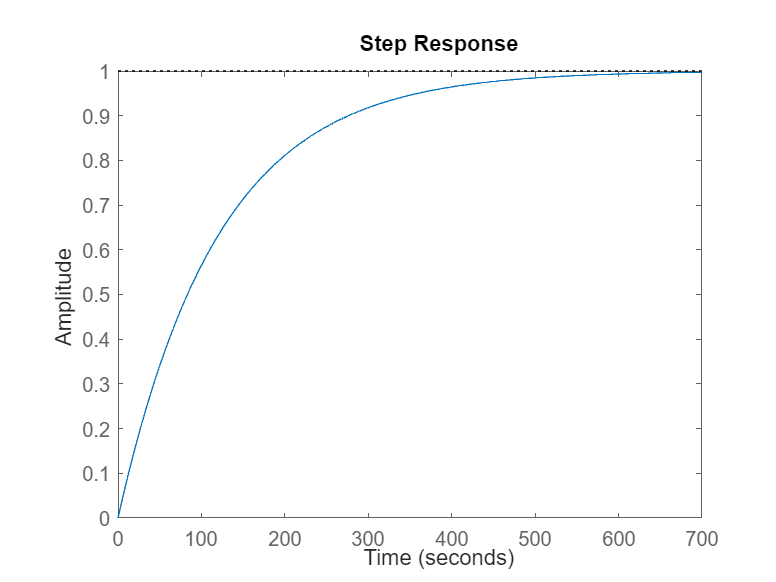


figure()
step(wref(1,1))

param.ctrl.K = Ksf;
fprintf("Step response for the calculated state feedback\n");

Step response for the calculated state feedback


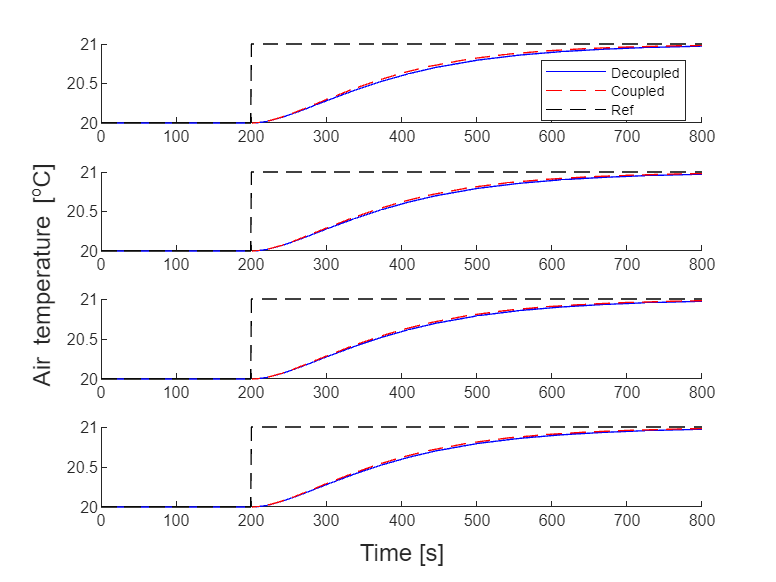

util.SimulateLinearStep(param,"Examination_Output_Feedback_Performance",0,800);

%saves the block version of K this is used further in some simulations
param.ctrl.K = Ksof*param.model.CySOF;
fprintf("Step response for the calculated static output feedback\n");

Step response for the calculated static output feedback


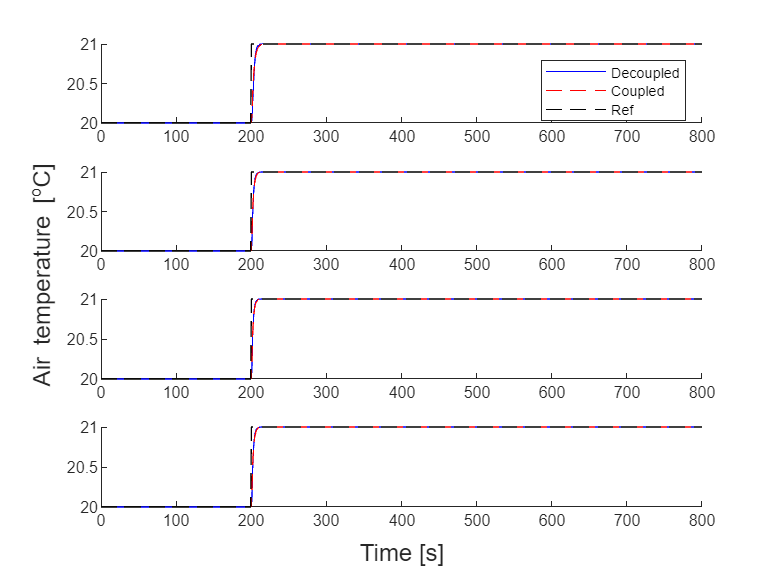

util.SimulateLinearStep(param,"Examination_Output_Feedback_Performance",0,800);


%saves a 3d matrix version of Ks this is used in the simulation of the nonlinear system.
param.ctrl.Ks = Ks;

function [P, Ksof] = constructVariables(param)
    ksof = cell(1,param.n);
    p = cell(1,param.n);
    for i=1:param.n
        p{i} = sdpvar(3);
        ksof{i} = sdpvar(1,2,'full');
    end
    P = blkdiag(p{1:end});
    Ksof = blkdiag(ksof{:});
end